c_H_i=15;c_H_o=25;
c_Cl_i=147;c_Cl_o=145;
c_Ga_i=c_Cl_i+0.2*c_H_i;
c_Ga_o=c_Cl_o+0.2*c_H_o;
E_Ga=26.64*log(c_Ga_i/c_Ga_o);
VV=E_Ga+0.00001;
Gabart=(c_Ga_i-c_Ga_o*exp(VV/26.64)).*(1./(1-exp(VV/26.64))).*(VV./(VV-26.64*log(c_Ga_i/c_Ga_o)));
pc=((30/(4*pi*(5)^2))*26.64/(9648500))*(10^7);
P_Clga=pc/Gabart;
P_Hga=P_Clga*0.2;

VV=linspace(-75.5,10.5,300);F=96485;
c_Cl_i=XX3(6);c_Cl_o=145-c_Cl_i;

c_Ga_i=c_Cl_i+0.2*c_H_i;c_Ga_o=c_Cl_o+0.2*c_H_o;

Clbart=(c_Cl_i-c_Cl_o*exp(VV/26.64)).*(1./(1-exp(VV/26.64))).*(VV./(VV-26.64*log(c_Cl_i/c_Cl_o)));
Hbart=(c_H_i-c_H_o*exp(VV/26.64)).*(1./(1-exp(VV/26.64))).*(VV./(VV-26.64*log(c_H_i/c_H_o)));
Gabart=(c_Ga_i-c_Ga_o*exp(VV/26.64)).*(1./(1-exp(VV/26.64))).*(VV./(VV-26.64*log(c_Ga_i/c_Ga_o)));

E_Cl=26.64*log(c_Cl_i/c_Cl_o);E_Ga=26.64*log(c_Ga_i/c_Ga_o);E_H=26.64*log(c_H_i/c_H_o);

G_Clga=10^(9)*(4*pi*(5*10^(-8))^2)*F*(100/26.64)*P_Clga*Clbart;
G_Hga=10^(9)*(4*pi*(5*10^(-8))^2)*F*(100/26.64)*P_Hga*Hbart;
G_Ga=10^(9)*(4*pi*(5*10^(-8))^2)*F*(100/26.64)*P_Clga*Gabart;

I_Clga=-10^(-3)*G_Clga.*(VV-E_Cl);
I_Hga=-10^(-3)*G_Hga.*(VV-E_H);
I_Ga=-10^(-3)*G_Ga.*(VV-E_Ga);

vv=E_Ga+0.000001;
Clbart1=(c_Cl_i-c_Cl_o*exp(vv/26.64)).*(1./(1-exp(vv/26.64))).*(vv./(vv-26.64*log(c_Cl_i/c_Cl_o)));
Hbart1=(c_H_i-c_H_o*exp(vv/26.64)).*(1./(1-exp(vv/26.64))).*(vv./(vv-26.64*log(c_H_i/c_H_o)));
Gabart1=(c_Ga_i-c_Ga_o*exp(vv/26.64)).*(1./(1-exp(vv/26.64))).*(vv./(vv-26.64*log(c_Ga_i/c_Ga_o)));

G_Clga1=10^(9)*(4*pi*(5*10^(-8))^2)*F*(100/26.64)*P_Clga*Clbart1;
G_Hga1=10^(9)*(4*pi*(5*10^(-8))^2)*F*(100/26.64)*P_Hga*Hbart1;
G_Ga1=10^(9)*(4*pi*(5*10^(-8))^2)*F*(100/26.64)*P_Clga*Gabart1;

vv=-5;
Clbart3=(c_Cl_i-c_Cl_o*exp(vv/26.64)).*(1./(1-exp(vv/26.64))).*(vv./(vv-26.64*log(c_Cl_i/c_Cl_o)));
Hbart3=(c_H_i-c_H_o*exp(vv/26.64)).*(1./(1-exp(vv/26.64))).*(vv./(vv-26.64*log(c_H_i/c_H_o)));
Gabart3=(c_Ga_i-c_Ga_o*exp(vv/26.64)).*(1./(1-exp(vv/26.64))).*(vv./(vv-26.64*log(c_Ga_i/c_Ga_o)));

G_Clga3=10^(9)*(4*pi*(5*10^(-8))^2)*F*(100/26.64)*P_Clga*Clbart3;
G_Hga3=10^(9)*(4*pi*(5*10^(-8))^2)*F*(100/26.64)*P_Hga*Hbart3;
G_Ga3=10^(9)*(4*pi*(5*10^(-8))^2)*F*(100/26.64)*P_Clga*Gabart3;

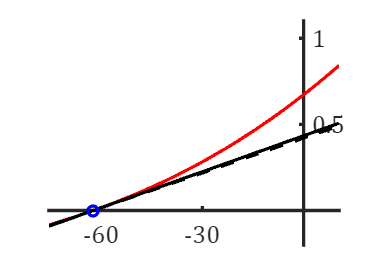

%extendfigure 1a
figure('Color','w')
E_Ga2=(G_Clga1*E_Cl+G_Hga1*E_H)./(G_Clga1+G_Hga1);
G_Ga2=G_Clga1+G_Hga1;
plot(VV,-I_Ga,'r','linewidth',2)
hold on
plot(VV,10^(-3)*G_Ga2*(VV-E_Ga2),'--k','linewidth',2)
plot(VV,10^(-3)*G_Ga1*(VV-E_Ga),'k','linewidth',2)
plot(E_Ga,0,'ob','linewidth',2)
set(gca,'linewidth',2,'Box','off','FontName','Cambria Math','FontSize',15)
set (gcf,'Position',[500,100,300,220])
set(gca,'XAxisLocation','origin','YAxisLocation','origin');
h = gca;
h.XTick = [-60 -30 0];
h.YTick = [0 0.5 1];
ylim([-0.2 1.1])

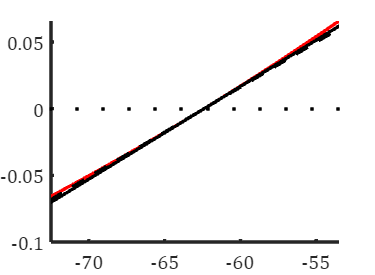

%extendfigure 1a inset figure 
figure('Color','w')
E_Ga2=(G_Clga1*E_Cl+G_Hga1*E_H)./(G_Clga1+G_Hga1);
G_Ga2=G_Clga1+G_Hga1;
plot(VV,-I_Ga,'r','linewidth',2)
hold on
plot(VV,10^(-3)*G_Ga2*(VV-E_Ga2),'--k','linewidth',2)
plot(VV,10^(-3)*G_Ga1*(VV-E_Ga),'k','linewidth',2)
set(gca,'linewidth',2,'Box','off','FontName','Cambria Math','FontSize',12)
set (gcf,'Position',[500,100,300,220])
xlim([-72.5 -53.5])
xx=linspace(-72.5,-53.5,12);yy=xx;yy(:)=0;
plot(xx,yy,'.k')

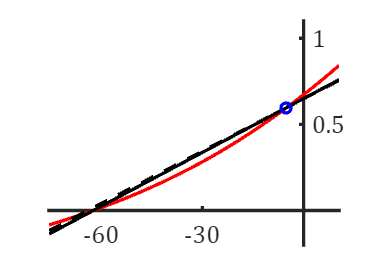

%extendfigure 1b
figure('Color','w')
E_Ga4=(G_Clga3*E_Cl+G_Hga3*E_H)./(G_Clga3+G_Hga3);
G_Ga4=G_Clga3+G_Hga3;
plot(VV,-I_Ga,'r','linewidth',2)
hold on
plot(VV,10^(-3)*G_Ga4*(VV-E_Ga4),'--k','linewidth',2)
plot(VV,10^(-3)*G_Ga3*(VV-E_Ga),'k','linewidth',2)
plot(-5,10^(-3)*G_Ga3*(-5-E_Ga),'ob','linewidth',2)
set(gca,'linewidth',2,'Box','off','FontName','Cambria Math','FontSize',15)
set (gcf,'Position',[500,100,300,220])
set(gca,'XAxisLocation','origin','YAxisLocation','origin');
h = gca;
h.XTick = [-60 -30 0];
h.YTick = [0 0.5 1];
ylim([-0.2 1.1])

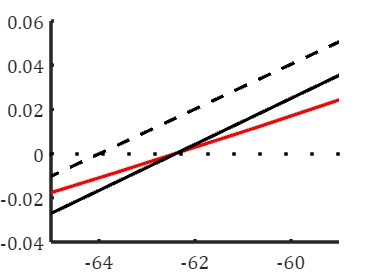

%extendfigure 1a inset figure
figure('Color','w')
E_Ga4=(G_Clga3*E_Cl+G_Hga3*E_H)./(G_Clga3+G_Hga3);
G_Ga4=G_Clga3+G_Hga3;
plot(VV,-I_Ga,'r','linewidth',2)
hold on
plot(VV,10^(-3)*G_Ga4*(VV-E_Ga4),'--k','linewidth',2)
plot(VV,10^(-3)*G_Ga3*(VV-E_Ga),'k','linewidth',2)
set(gca,'linewidth',2,'Box','off','FontName','Cambria Math','FontSize',12)
set (gcf,'Position',[500,100,300,220])
xlim([-65 -59])
xx=linspace(-65,-59,12);yy=xx;yy(:)=0;
plot(xx,yy,'.k')

c_Na_i=XX3(5);c_Na_o=155-c_Na_i;
c_K_o=XX3(4);c_K_i=100-c_K_o;
r=(c_K_i-c_K_o)/(c_Na_o-c_Na_i);
c_Gl_o=c_K_o+r*c_Na_o;
Glbart=c_Gl_o;
pc=((30/(4*pi*(5)^2))*26.64/(9648500))*(10^7);
P_Kgl=pc/Glbart;
P_Nagl=r*P_Kgl;
VV=-100.5:1:100.5;F=96485;
c_Na_i=XX3(5);c_Na_o=155-c_Na_i;
c_K_o=XX3(4);c_K_i=100-c_K_o;
c_Ca_o=2;c_Ca_i=0.0001;r3=30;
c_Gl_i=c_K_i+r*c_Na_i;c_Gl_o=c_K_o+r*c_Na_o;
c_Gl_i3=c_K_i+r*c_Na_i+2*r3*c_Ca_i./(1+exp(-VV/26.64));c_Gl_o3=c_K_o+r*c_Na_o+2*r3*c_Ca_o*exp(-VV/26.64)./(1+exp(-VV/26.64));

Kbart=(c_K_i-c_K_o*exp(-VV/26.64)).*(1./(1-exp(-VV/26.64))).*(VV./(VV-26.64*log(c_K_o/c_K_i)));
Nabart=(c_Na_i-c_Na_o*exp(-VV/26.64)).*(1./(1-exp(-VV/26.64))).*(VV./(VV-26.64*log(c_Na_o/c_Na_i)));
Cabart=(c_Ca_i-c_Ca_o*exp(-2*VV/26.64)).*(1./(1-exp(-2*VV/26.64))).*(VV./(VV-0.5*26.64*log(c_Ca_o/c_Ca_i)));
Glbart=(c_Gl_i-c_Gl_o*exp(-VV/26.64)).*(1./(1-exp(-VV/26.64))).*(VV./(VV-26.64*log(c_Gl_o/c_Gl_i)));
Glbart3=(c_Gl_i3-c_Gl_o3.*exp(-VV/26.64)).*(1./(1-exp(-VV/26.64))).*(VV./(VV-26.64*log(c_Gl_o3./c_Gl_i3)));

E_Na=26.64*log(c_Na_o/c_Na_i);E_K=26.64*log(c_K_o/c_K_i);E_Ca=0.5*26.64*log(c_Ca_o/c_Ca_i);
E_Gl=26.64*log(c_Gl_o/c_Gl_i);E_Gl3=26.64*log(c_Gl_o3/c_Gl_i3);

G_Kgl=10^(9)*(4*pi*(5*10^(-8))^2)*F*(100/26.64)*P_Kgl*Kbart;
G_Nagl=10^(9)*(4*pi*(5*10^(-8))^2)*F*(100/26.64)*P_Nagl*Nabart;
G_Gl=10^(9)*(4*pi*(5*10^(-8))^2)*F*(100/26.64)*P_Kgl*Glbart;
G_Gl3=10^(9)*(4*pi*(5*10^(-8))^2)*F*(100/26.64)*P_Kgl*Glbart3;
G_Cagl=10^(9)*(4*pi*(5*10^(-8))^2)*4*F*(100/26.64)*r3*P_Kgl*Cabart;

I_Kgl=-10^(-3)*G_Kgl.*(VV-E_K);
I_Nagl=-10^(-3)*G_Nagl.*(VV-E_Na);
I_Cagl=-10^(-3)*G_Cagl.*(VV-E_Ca);
I_Gl=-10^(-3)*G_Gl.*(VV-E_Gl);
I_Gl3=-10^(-3)*G_Gl3.*(VV-E_Gl3);

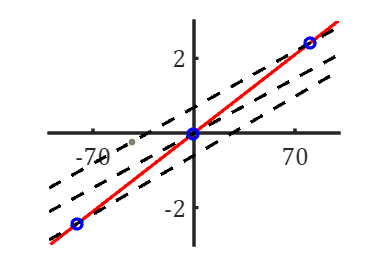

%extendfigure 1c
figure('Color','w')
E_Gl2=(G_Kgl*E_K+G_Nagl*E_Na)./(G_Kgl+G_Nagl);
G_Gl2=G_Nagl+G_Kgl;
plot(VV(2:5:202),-I_Gl(2:5:202),'r','linewidth',2)
hold on
ii1=21;
plot(VV,10^(-3)*G_Gl2(ii1)*(VV-E_Gl2(ii1)),'--k','linewidth',2)
plot(VV(ii1),10^(-3)*G_Gl2(ii1)*(VV(ii1)-E_Gl2(ii1)),'ob','linewidth',2)
ii1=101;
plot(VV,10^(-3)*G_Gl2(ii1)*(VV-E_Gl2(ii1)),'--k','linewidth',2)
plot(VV(ii1),10^(-3)*G_Gl2(ii1)*(VV(ii1)-E_Gl2(ii1)),'ob','linewidth',2)
ii1=182;
plot(VV,10^(-3)*G_Gl2(ii1)*(VV-E_Gl2(ii1)),'--k','linewidth',2)
plot(VV(ii1),10^(-3)*G_Gl2(ii1)*(VV(ii1)-E_Gl2(ii1)),'ob','linewidth',2)

set(gca,'linewidth',2,'Box','off','FontName','Cambria Math','FontSize',15)
set (gcf,'Position',[500,100,300,220])
set(gca,'XAxisLocation','origin','YAxisLocation','origin');
h = gca;
ylim([-3 3])
h.XTick = [-70 70];
h.YTick = [-2 0 2];

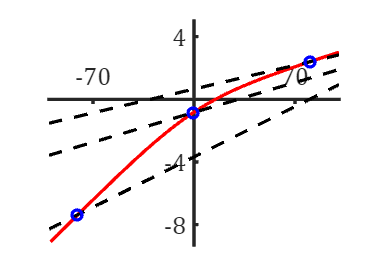

%extendfigure 1d
figure('Color','w')
E_Gl4=(G_Kgl*E_K+G_Nagl*E_Na+G_Cagl*E_Ca)./(G_Kgl+G_Nagl+G_Cagl);
G_Gl4=G_Nagl+G_Kgl+G_Cagl;
plot(VV(2:5:202),-I_Cagl(2:5:202)-I_Kgl(2:5:202)-I_Nagl(2:5:202),'r','linewidth',2')
hold on
ii1=21;
plot(VV,10^(-3)*G_Gl4(ii1)*(VV-E_Gl4(ii1)),'--k','linewidth',2)
plot(VV(ii1),10^(-3)*G_Gl4(ii1)*(VV(ii1)-E_Gl4(ii1)),'ob','linewidth',2)
ii1=101;
plot(VV,10^(-3)*G_Gl4(ii1)*(VV-E_Gl4(ii1)),'--k','linewidth',2)
plot(VV(ii1),10^(-3)*G_Gl4(ii1)*(VV(ii1)-E_Gl4(ii1)),'ob','linewidth',2)
ii1=182;
plot(VV,10^(-3)*G_Gl4(ii1)*(VV-E_Gl4(ii1)),'--k','linewidth',2)
plot(VV(ii1),10^(-3)*G_Gl4(ii1)*(VV(ii1)-E_Gl4(ii1)),'ob','linewidth',2)

set(gca,'linewidth',2,'Box','off','FontName','Cambria Math','FontSize',15)
set (gcf,'Position',[500,100,300,220])
set(gca,'XAxisLocation','origin','YAxisLocation','origin');
h = gca;
h.XTick = [-70 70];
h.YTick = [-8 -4 0 4];
ylim([-9.3 5])